# Simple Quadcopter Propeller Model

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

When modeling a quadcopter, the propeller is a component that uses a motor to convert electrical energy into mechanical thrust. A good propeller model must be simple enough for control design while being physically meaningful. We therefore start with the simplest useful propeller model that takes into account units and scaling. Complexity can be introduced later.

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline** using the icon   at the top right of the Live Editor pane.

## Motivation

You change only one thing on a quadcopter: replace all four 5‑inch propellers with 10‑inch propellers. Can you predict how the new quadcopter will behave? Let's explore this question with both local (blade element) and global (momentum theory) approaches. If we approach the problem at both scales and reach the same conclusion, that is an additional indication that the underlying fundamentals agree. 

## Momentum theory 

First, consider a global approach where we model the propeller as an actuator disk 

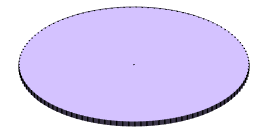 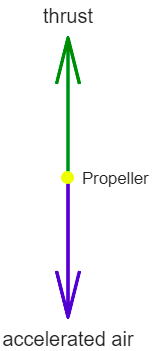

that accelerates air downward. Then

$\dot{m} = \rho A v = \rho \pi r^2 v$, 

where

- $\dot{m}$ = mass flow rate of air [kg/s]

- $v$ = downward air velocity [m/s]

- $\rho$ = the mass density of air [kg/m^3] 

- $r$ = the radius of the propeller [m] 

The air speed induced by the propeller scales with blade tip speed, so $v \propto \omega r$ where $\omega$ is the radial velocity in radians per second. This gives us

$\dot{m} \propto \rho \pi r^3 \omega$.

The induced velocity change is also proportional to $\omega r$. From Newton's second law, the thrust force, $T$, can be expressed as: 


$$T = \dot{m}\Delta v$$


$T \propto \rho  \pi r^2 (\omega r)^2 = \rho \pi r^4 \omega^2$. 

**Note:** [Some derivations](https://ocw.mit.edu/ans7870/16/16.unified/propulsionS04/UnifiedPropulsion7/UnifiedPropulsion7.htm) use the diameter of the propeller rather than the radius. Recall that for a diameter $D$, we can write $r  = \frac{D}{2}$, so $T \propto \rho \pi \left(\frac{D}{2}\right)^4\omega^2$. This also gives a fourth-order dependence of the thrust on the propeller diameter, simply by changing the constant factor.

### Blade element reasoning

Let's also consider a local approach, where we look at one small blade section at radius $x$. The local tangential speed is $v(x) = \omega x$. The dynamic pressure is $q = \frac{1}{2}\rho v^2 = \frac{1}{2}\rho \omega^2x^2$. The incremental thrust on the blade element is proportional to the dynamic pressure times the area element, $dA = c(x)\; dx$ where $c(x)$ is the cross-sectional width of the propeller at radius $x$.  A geometrically similar blade is one where every cross‑section is the *same airfoil*, just shrunk or stretched. Real propellers break geometric similarity near the root and the tip. Still, for a simple model we'll assume that geometric similarity holds. This means that $c(x)/r$ is a constant, so $c \propto r$. Therefore, the incremental thrust is:


$$\matrix{dT &\propto& q\cdot c(x) \; dx  \cr dT &\propto &\rho \omega^2 x^2r\; dx.}$$


Then the total thrust is


$$\matrix{\displaystyle T &\propto& \int_0^r \rho \omega^2 x^2r \; dx \cr &\propto &\rho \omega^2 r^4. \hspace{0.4in}}$$


**Pro-Tip:** Different propeller designs make different choices for $c$, from an inefficient $c = \text{constant}$ that puts lots of pressure on the tips of propellers to a better $c = c_0\left(1-k\frac{x}{r}\right)$ or an even better $c \propto \sqrt{1-\left(\frac{x}{r}\right)^2}$ to create propellers with more uniform force along their length. 

### Dimensional analysis

We want thrust, $T$, which, as a force, has units of $\text{kg}\cdot\text{m}/\text{s}^2$. The components to include are:

- Mass density $\rho$  [$\text{kg}/\text{m}^3$]

- Angular speed $\omega$  [$1/\text{s}$]

- Propeller radius $r$  [$\text{m}$].

The only way to combine these elements to create the correct dimensions is if $T \propto \rho r^4\omega^2$. For purposes of numerical computation, we can define a dimensionless coefficient $C_T$ such that $T = C_T \rho r^4\omega^2$. By measuring the thrust of a specific propeller at a known speed $\omega$, we can compute $C_T$ and model the thrust as we change the radius, the mass density, and the rotational speed within the domain where the model makes sense. 

### Modeling assumptions

We assumed:

- The propeller has rigid, fixed‑pitch blades $\rightarrow$ the geometric assumptions are constant

- Flow is incompressible $\rightarrow$ the value of $\rho$ is constant

- Thrust acts along the propeller axis $\rightarrow$ the propeller is fixed-pitch

- No blade flapping, no induced velocity modeling $\rightarrow$ the geometric assumptions are constant

These assumptions are valid for:

- Subsonic flow

- Forward speed is small (hover or slow flight)

- Props are fixed‑pitch

- Reynolds numbers are moderate

## Thrust model

These assumptions give us the simplest physically meaningful thrust model as:

$T = k_T \omega^2$.

Where:

- $T$ = thrust force [N]

- $\omega$ = angular speed of the propeller [rad/s]

- $k_T$ = $C_T\rho r^4$ is a thrust coefficient [N/(rad/s)^2]

**Physical interpretation**

- Faster rotation → higher blade tip speed

- Higher tip speed → larger dynamic pressure

- The resulting thrust grows quadratically with $\omega$

 **Exercise 1.**

What propeller speed is required for a quadcopter of mass $M = 0.54$ kg with a thrust coefficient of $k_T = 1.072\times 10^{-5}$ to hover? Use $g = 9.81 \text{ m}/\text{s}^2$. Call your solution `omega_hover`.

**Solution:**


$$4 k_T \omega^2 = Mg$$



$$\omega = \sqrt{\frac{Mg}{4k_T}}$$


M = 0.54; % kg
g = 9.81;
kT = 1.072e-5;
omega_hover = sqrt(M*g/(4*kT))
CheckEx1(omega_hover)

## Reaction (drag) torque model

Let $V_{\text{a}}(x)$ be the local inflow velocity. For a hovering propeller, this inflow velocity is just the tangential component $V_{\text{a}}(x) = \omega x$. 

 **Pro-tip (Advanced considerations).** The [aerodynamic propeller block](https://www.mathworks.com/help/sdl/ref/aerodynamicpropeller.html) will be the fundamental propeller used in our models throughout this courseware. Note the distinctions between thrust, lift, drag, and torque, as well as the airflow through the propeller, $V_a$, and the speed of the vehicle $V_v$.  

When forward motion is involved, the airflow,$\vec{V}_{\text{a}} = \omega x \hat{\theta} + \left(V_{v} + v_i\right)\hat{z}$, picks up an additional perpendicular term that can be expressed in terms of the aircraft forward speed,$V_{v}$,  and the induced axial velocity through the disk,$v_i$. Thus, in general, $V_{\text{a}} = \sqrt{(\omega x)^2 + (V_{v} + v_i)^2}$, so when $\omega x >> V_{v}$, such as when the forward velocity is 0, it is reasonable to approximate $V_{\text{a}} \approx \omega x$. However, in forward flight this changes. Near the hub, $\omega x$ is small so $V_{v}$ will dominate with $V_{\text{a}}\approx V_{v} + v_i$, but near the tip, rotation will still dominate with $V_{\text{a}}\approx \omega x$. 

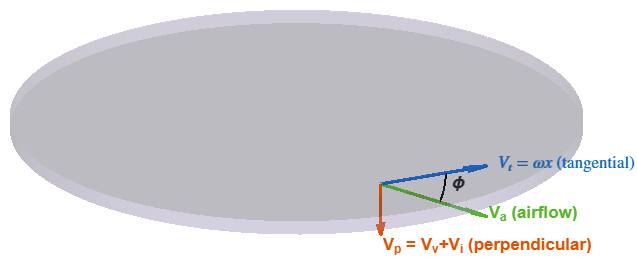

 **Exercise 2.** Define the inflow angle $\phi$ by $\tan(\phi) = \frac{V_{v} + v_i}{\omega x}$. 

a. Near the hub, the value of $\phi$:

CheckEx2("increases","a")

b. Near the tip, the value of $\phi$:

CheckEx2("decreases","b");

For a blade element at radius $x$, the local Reynolds number is 

$\text{Re}(x) = \frac{\rho V_{\text{a}}(x)c(x)}{\mu}$.

**Cautionary Note (Aerodynamic Theory):** The Reynolds number depends on both geometry (chord $c$) and kinematics (local velocity $V_{\text{a}}$). This means that even geometrically similar propeller blades can operate in different Reynolds regimes. Blade-element theory assumes that if the geometry is similar, then the section aerodynamics are similar. This assumption is only valid when the thrust coefficient and the torque coefficient are Reynolds-insensitive over the operating range. At a low Reynolds number, stalls occur earlier, the maximum thrust coefficient is lower, drag is higher, and laminar separation bubbles appear. Even on a single blade, because of the proportionality to $V_{\text{a}}\cdot c$, there will be Reynolds number variation from near 0 towards the shaft and much higher near the tip. This means that inner blade sections may exhibit low-Re aerodynamics while the outer sections behave as classical airfoils. Careful shaping of the propeller blade can minimize the effects, but as the modeling fidelity improves, it will be important to consider this.

### Drag on a blade element

For a blade element at radius $x$ with width $dx$, the incremental section drag force is

$dD = \frac{1}{2}\rho V_{\text{a}}^2(x) c(x) C_Q\; dx$.

where $C_Q$ is the torque coefficient, which depends on factors including the Reynolds number. For propeller analyses near the hover regime, 

$V_{\text{a}}(x) \approx \omega x$. 

So, by substitution, we have an $x$-dependence of

$\frac{dD}{dx} \propto x^2c(x)C_Q$,

because $C_Q$ is not constant along the blade due to its dependence on the Reynolds number.

### Torque

Since torque is force times moment arm, the incremental torque is $dQ = xdD$, or in other words

$\frac{dQ}{dx} = \frac{1}{2}\rho V_{\text{a}}^2(x)c(x)C_Q x$.

In the near-hover domain, this can be simplified to 

$\frac{dQ}{dx} \propto C_Q\omega^2 x^3 c(x)$    and thus, when $c \propto r$,     $Q \propto C_Q\omega^2 r^5$.

More generally, $\displaystyle Q \propto \int_0^r \frac{1}{2}\omega^2x^3c(x)C_Q\; dx$ and thus, the power $P$ required by the propeller can be expressed as $\displaystyle P = \omega Q \propto \int_0^r \frac{1}{2}\omega^3x^3c(x)C_Q\; dx$.

As the propeller spins, aerodynamic drag produces a reaction torque on the motor shaft:


$$Q = k_m \omega^2$$


Where:

- $Q$ = torque resisting rotation [N$\cdot$m]

- $k_m$ = drag (moment) coefficient including $C_Qr^5$.

## Impact on Quadcopter Design

Torque acts about the axis of rotation, causing the yaw motion of the vehicle. For a quadcopter, because torque acts in a direction opposite to the spin of the propeller, balanced operation requires paired sets of counter-rotating propellers. The thrust acts in the opposite direction to the air jet.

We encode the direction of rotation with a sign $\epsilon=\pm1$:


$$Q_z = \epsilon \, k_m \, \omega^2$$


function [T,Q] = SimplePropellerModel(omega, kT, km, spinDir)
% SimplePropellerModel
% Simple quadcopter propeller model
%
% Inputs:
%   omega   - rotational speed [rad/s]
%   kT      - thrust coefficient [N/(rad/s)^2]
%   km      - drag coefficient   [N*m/(rad/s)^2]
%   spinDir - +1 (CCW) or -1 (CW)
%
% Outputs:
%   T       - thrust force [N]
%   Q       - reaction torque about axis of rotation [N*m]

T   = kT * omega.^2;
Q = spinDir * km * omega.^2;
end

  **Try**. With given values of $k_T$ and $k_m$, use the simple propeller model to observe the relationships between rotational speed, thrust, and drag torque by running this section of code.

kT = 1.8e-5;
km = 2.0e-7;
omega = linspace(0,900,200);
spinDir = 1;

[T,Q] = SimplePropellerModel(omega, kT, km, spinDir);

figure
yyaxis left
plot(omega, T, "LineWidth",1.5);
ylabel("Thrust [N]");

yyaxis right
plot(omega, Q, "--", "LineWidth",1.5);
ylabel("Torque [N m]");

xlabel("\omega [rad/s]");
title("Simple propeller model: thrust and drag torque");

 **Reflect**. Why does thrust increase much faster than torque for the same increase in $\omega$?

 **Exercise 3.** Build a Simulink model implementing the simple propeller model. 

- Use constant inputs of $\omega$, $k_m$, $k_T$, and $\epsilon$

- Implement the formulas from `SimplePropellerModel` using Simulink blocks. Split signals, as needed.

- Output values for thrust and torque in display blocks. 

open("SimplePropellerModel_Soln.slx");

### Further Design Considerations

There are many parameters to consider in propeller design that go far beyond the discussions here. More of the equations and details are described in the documentation for the [Aerodynamic Propeller block](https://www.mathworks.com/help/sdl/ref/aerodynamicpropeller.html). 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

function CheckEx1(speed)
M = 0.54; % kg
g = 9.81;
kT = 1.072e-5;
omega_hover = sqrt(M*g/(4*kT));
if abs(omega_hover-speed) < 5e-1
    disp("Correct! The calculated hover speed matches the expected value.")
    disp("The propeller needs to be rotating at approximately " + round(speed) + " rad/s or " + round(60*speed/(2*pi)) + " rpm.")
elseif abs(omega_hover^2-speed) < 1e-3
    disp("Incorrect. Did you remember the square root?")
elseif abs(omega_hover*2 - speed) < 1e-3
    disp("Incorrect. Did you remember that a quadcopter has four propellers?")
elseif speed == 0
    disp("This is the default value. Please compute a nonzero speed.")
else
    disp("Incorrect. Please check your calculation and try again.")
end
end

function CheckEx2(Soln,Part)
arguments
    Soln (1,1) string {mustBeMember(Soln,["default","decreases","same","increases"])}
    Part (1,1) string {mustBeMember(Part,["a" "b"])}
end

switch Soln
    case "default"
        disp("This is the default. Please answer the question.")
    case "decreases"
        if Part=="b"
            disp("Correct.")
            displayFormula('"This dependence on radial distance is why forward-flight propellers must be twisted."')
        else
            disp("Incorrect.")
            displayFormula(['"Remember that the angle "' "phi" '" approaches 0 as "' "tan(phi)" '" approaches 0."'])
        end
    case "same"
        disp("Incorrect.")
        displayFormula(['"How can the angle "' "phi" '" not change when it depends on the value of x?"'])
    case "increases"
        if Part == "a"
            disp("Correct.")
        else
            disp("Incorrect.")
            displayFormula(['"Remember that "' "phi" '" approaches "' "pi/2" '" as "' "tan(phi)" '" approaches infinity."'])
        end
end
end